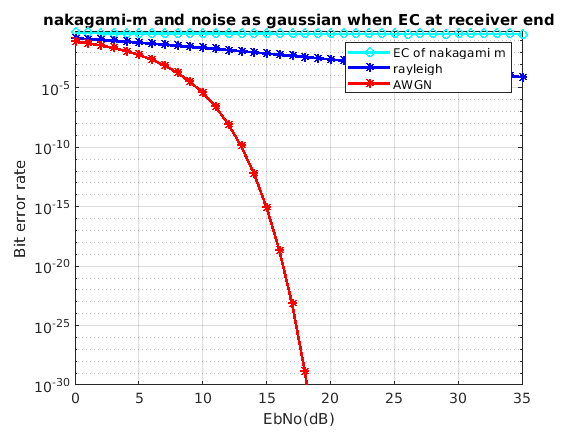

clc;
close all;
clear all;
pd = makedist('Nakagami','mu',9,'omega',6);
msg= random(pd,1000,1);
data=[];
t=0:.01:.99;
c=cos(2*pi*10*t);%carrier signal & it's a matrix of length 1X100(bcoz for each t, there's a c).let fc=10hz
for i=1:10
    if msg(i)<=0
        d=-1*ones(1,10);
    else
        d=ones(1,10);
    end
 data=[data d];   
end
 vbfsk=[];
for i=1:100
vbfsk=[vbfsk cos(2*pi*10*t+(msg(i)*2*pi*5*t))];
end

x = 1; % signal to transmit Eb = 1
T = 10000; %number of simulation runs per EbN0 %50000
N=10^6;
for EbN0 = 0:1:35 %dB
    NdB_EbN0= 10^(EbN0/10); 
    E_b = 1/(NdB_EbN0); 
    error = 0; %set error counter to 0
    error1=0;
    fun = makedist('Nakagami','mu',9,'omega',1);
    nakagami = random(fun,1000,1);
    fun_1 = makedist('Nakagami','mu',5,'omega',3);
    nakagami_1 = random(fun_1,1000,1);
        for t = 1:T %  count the errors
            gaussian_1 = sqrt(E_b/2)*randn; %noise for the first
            gaussian_2 = sqrt(E_b/2)*randn; %noise for the 2nd
            rayleigh_1 = sqrt(0.5)*abs(randn + 1i*randn); %rayleigh noise
            rayleigh_2 = sqrt(0.5)*abs(randn + 1i*randn);
            Added_noise_1=sqrt(E_b/2)*randn+sqrt(0.5)*abs(randn + 1i*randn);
            Added_noise_2=sqrt(E_b/2)*randn+sqrt(0.5)*abs(randn + 1i*randn);
            %Equal Gain combining
            EGC1 = x*vbfsk+Added_noise_1; % Signal 1
            EGC2 = x*vbfsk+Added_noise_2; % Signal 2
            EGC = 0.5*(EGC1+EGC2); 
            if EGC > 0 %define decision region as 0 
               error = error + 1;
           end
        end

    BER(EbN0+1) = error/(T);
end
figure
EbNo=0:1:35; %changed from 10
linear_EbNo = 10.^(EbNo/10);
theoryBerAWGN = 0.5*erfc(sqrt(10.^(EbNo/10)));
theoryBer = 0.5.*(1-sqrt(linear_EbNo ./(linear_EbNo +1)));
semilogy(EbNo,BER,'c-o',EbNo,theoryBer,'b*-',EbNo,theoryBerAWGN,'r*-','linewidth',2); % plot EG BER vs EbNo
hold on;
grid on;
axis([0 35 10^-30 0.5])
legend('EC of nakagami m','rayleigh','AWGN');
xlabel('EbNo(dB)') %Label for x-axis
ylabel('Bit error rate') %Label for y-axis
title('nakagami-m and noise+awgn as gaussian when EC at receiver end');


gam0 = 5;
av_snr2=[];
av_snr1=[];
snr=[1:35];
fun_1 = makedist('Nakagami','mu',5,'omega',3);
    nakagami_1 = random(fun_1,1000,1);
    fun_2 = makedist('Nakagami','mu',5,'omega',2);
    nakagami_2 = random(fun_2,1000,1);
%nakagami_1=sqrt(0.5)*abs(randn(1000,1)+1i*randn(1000,1)); %rayleigh channel 1
%nakagami_2=sqrt(0.5)*abs(randn(1000,1)+1i*randn(1000,1)); %rayleigh channel 2
%%Adding Noise
A=[];
B=[];
for i=1:length(snr)
    sig1=awgn(nakagami_1,snr(i));
    A=[A,sig1];
    sig2=awgn(nakagami_2,snr(i));
    B=[B,sig2];
end
n=size(A);
for k=1:n(2)
    asn1=A(:,k);
    asn2=B(:,k);
    avg=0;
    aa=0;
for i=1:length(B)
    wgt=(abs(asn1(i))^2)+(abs(asn2(i))^2)/2;
    avg=avg+wgt;
    aa=aa+abs(asn1(i)^2);
end
av_snr2=[av_snr2,avg];
av_snr1=[av_snr1,aa];
end
gr = gam0./(snr.*av_snr2);
gr1 = gam0./(snr.*av_snr1);
for i = 1:length(gr)
    pout2(i) = (1-(exp(-2*gr(i)))-((sqrt(pi*gr(i)))*(exp(-gr(i)))))*(1-2*(erfc(sqrt(gr(i)))));
    pout1(i) = (1-(exp(-2*gr1(i)))-((sqrt(pi*gr1(i)))*(exp(-gr1(i)))))*(1-2*(erfc(sqrt(gr1(i)))));
end
%plotting of figure

subplot(411);
plot(msg);
title('nakagami m data');

subplot(412);
plot(data);axis([0 100 -1.5 1.5])
title('Digital data');
subplot(413)
plot(c);axis([0 100 -1.5 1.5])
title('Unmodulated carrier');
 
%disp(data);
disp(vbfsk);

  Column 1

    1.0000

  Column 2

    0.2716

  Column 3

   -0.8525

  Column 4

   -0.7346

  Column 5

    0.4535

  Column 6

    0.9809

  Column 7

    0.0793

  Column 8

   -0.9378

  Column 9

   -0.5887

  Column 10

    0.6181

  Column 11

    0.9244

  Column 12

   -0.1160

  Column 13

   -0.9874

  Column 14

   -0.4203

  Column 15

    0.7591

  Column 16

    0.8326

  Column 17

   -0.3069

  Column 18

   -0.9993

  Column 19

   -0.2359

  Column 20

    0.8712

  Column 21

    0.7091

  Column 22

   -0.4860

  Column 23

   -0.9731

  Column 24

   -0.0425

  Column 25

    0.9500

  Column 26

    0.5585

  Column 27

   -0.6466

  Column 28

   -0.9097

  Column 29

    0.1525

  Column 30

    0.9926

  Column 31

    0.3866

  Column 32

   -0.7826

  Column 33

   -0.8117

  Column 34

    0.3417

  Column 35

    0.9973

  Column 36

    0.1999

  Column 37

   -0.8887

  Column 38

   -0.6826

  Column 39

    0.5179

  Column 40

    0.9639

  Column 

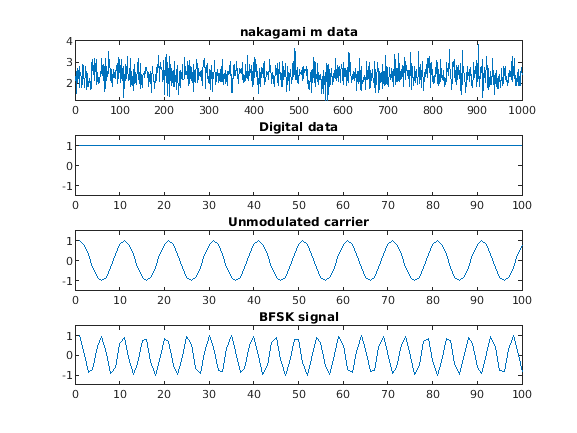

subplot(414);
plot(vbfsk);axis([0 100 -1.5 1.5])
title('BFSK signal');

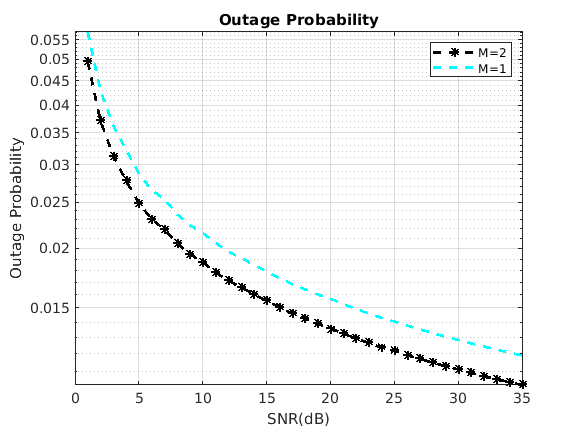


figure()
semilogy(snr,pout2,'k*--',snr,pout1,'c--','linewidth',2);

hold on;

grid on;
 xlabel('SNR(dB)');
 ylabel('Outage Probability');
 legend('M=2','M=1')
title('Outage Probability')